## GA controlled PID controller for AVR system

## AVR Transfer Function

num = [0.1, 10];
den = [0.0004, 0.0454, 0.555, 1.52, 11];

sys = tf(num, den);

### Step response

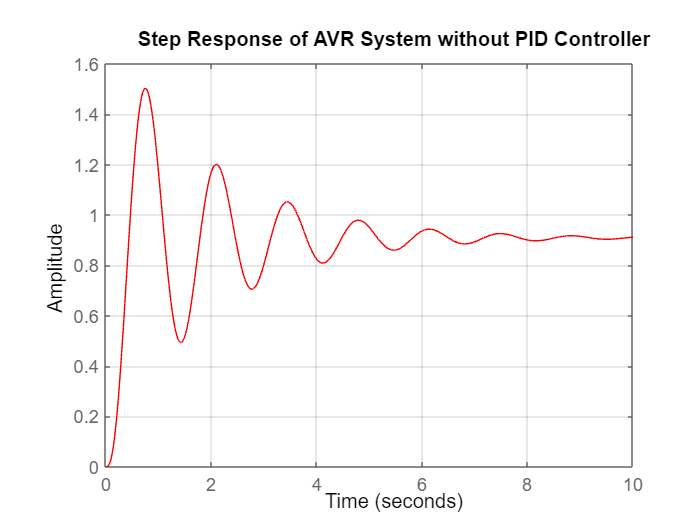

step(sys , 'r');
grid on;
title('Step Response of AVR System without PID Controller');

### Parameters

[y, t] = step(sys);

info = stepinfo(y, t);

Ess = abs(1 - y(end))                           % Steady-state error

Ess = 0.0894

Mp = (max(y)- y(end)) / y(end)                  % Maximum overshoot

Mp = 0.6502

Ts = info.SettlingTime                          % Settling time

Ts = 6.9878

Tr = info.RiseTime                              % Rise time

Tr = 0.2613


beta = 1;
W = (1-exp(-beta))*(Mp + Ess) + (exp(-beta))*(Ts - Tr);

disp("Performance criterion without PID Controller : " + num2str(W));

Performance criterion without PID Controller : 2.942


## AVR with a PID Controller


num_f = 10;
den_f = [0.04, 0.54, 1.5, 1];
AVR_ForwardPath = tf(num_f, den_f);

num_b = 1;
den_b = [0.01, 1];
AVR_BackwardPath = tf(num_b, den_b);

% PID controller parameters from the Paper
Kp = 0.6570;        % Proportional gain
Ki = 0.5389;        % Integral gain
Kd = 0.2458;        % Derivative gain

pid_controller = pid(Kp, Ki, Kd);

sys_with_pid = feedback(pid_controller * AVR_ForwardPath, AVR_BackwardPath);

W_PID = PerformanceCriterion(Kp, Ki, Kd, 1);
disp("Performance criterion with optimal PID Controller : " + num2str(W_PID));

Performance criterion with optimal PID Controller : 0.22905


### Step Response

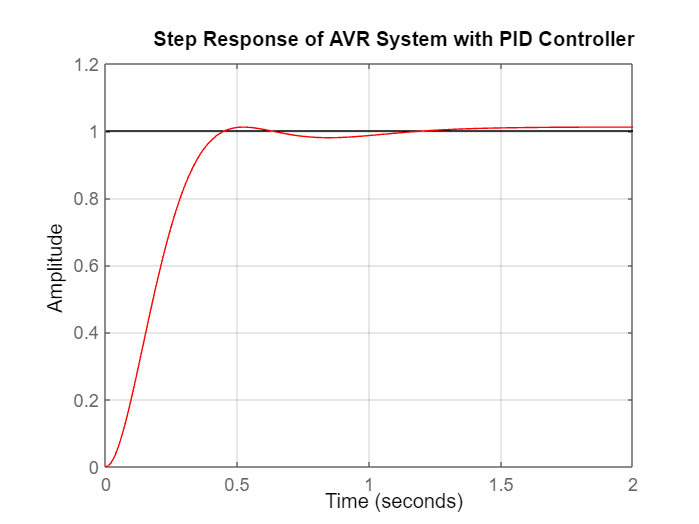

t = 0:0.01:2; 
step(sys_with_pid, t, 'r');
grid on;
title('Step Response of AVR System with PID Controller');

### Parameters

[y, t] = step(sys_with_pid);

info_PID = stepinfo(y, t);

% Extract relevant performance metrics
Ess1 = abs(1 - y(end))              % Steady-state error

Ess1 = 3.5153e-04

Mp1 = (max(y)- y(end)) / y(end)     % Maximum overshoot

Mp1 = 0.0112

Ts1 = info.SettlingTime             % Settling time

Ts1 = 6.9878

Tr1 = info.RiseTime                 % Rise time

Tr1 = 0.2613

## GA

### Initialization

objective_function = @(K) PerformanceCriterion(K(1), K(2), K(3), beta);

dt = 0.001;            
PopSize = 25;           
MaxGenerations = 10;
beta = 1.5;
initial_guess = [0, 0, 0]; 
lower_bound = [0, 0, 0]; 
upper_bound = [1.5, 1, 1]; 
population = rand(PopSize, 3) .* (upper_bound - lower_bound) + lower_bound;


### Algorithmn


for generation = 1:MaxGenerations
    fitness = zeros(PopSize, 1);
    for i = 1:PopSize
        fitness(i) = objective_function(population(i, :));
    end

    [~, sorted_indices] = sort(fitness);
    parents_indices = sorted_indices(1:floor(PopSize/2));
    parents = population(parents_indices, :);

    crossover_point = randi([1, 2], floor(PopSize/2), 1);
    offspring = [parents(mod(1:floor(PopSize/2), length(parents)) + 1, 1:crossover_point), ...
                 parents(mod(1:floor(PopSize/2), length(parents)) + 1, crossover_point+1:end)];

    mutation_rate = 0.1;
    mask = rand(size(offspring)) < mutation_rate;
    offspring(mask) = offspring(mask) + randn(sum(mask(:)), 1) * 0.1; % Mutating with random noise

    population(end-length(offspring)+1:end, :) = offspring;

    performance_criterion_values(generation) = min(fitness);
end

best_fitness = inf;
best_solution = [];
for i = 1:PopSize
    current_fitness = objective_function(population(i, :));
    if current_fitness < best_fitness
        best_fitness = current_fitness;
        best_solution = population(i, :);
    end
end


### Result

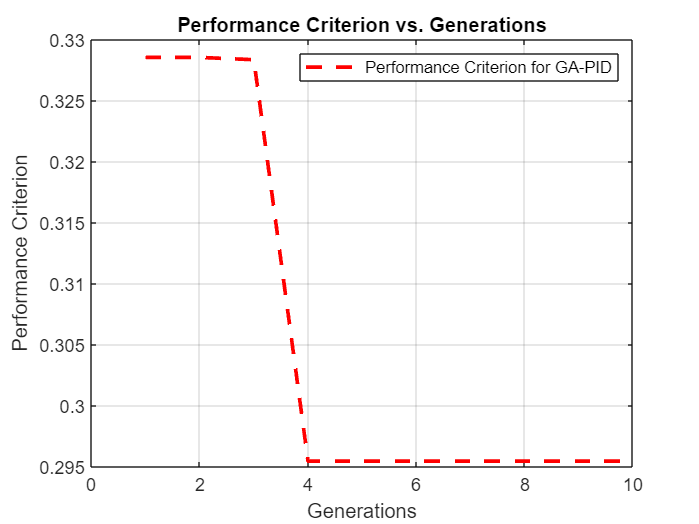

% Plot performance criterion values over generations
plot(1:generation, performance_criterion_values,'r--', 'LineWidth', 2);
xlabel('Generations');
ylabel('Performance Criterion');
legend('Performance Criterion for GA-PID');
title('Performance Criterion vs. Generations');
grid on;

kp_optimized = best_solution(1); 
ki_optimized = best_solution(2); 
kd_optimized = best_solution(3); 

disp(['Optimized PID controller parameters: ', num2str(best_solution)]);

Optimized PID controller parameters: 0.95805     0.85723     0.36241


disp(['Corresponding best fitness value: ', num2str(best_fitness)]);

Corresponding best fitness value: 0.29546


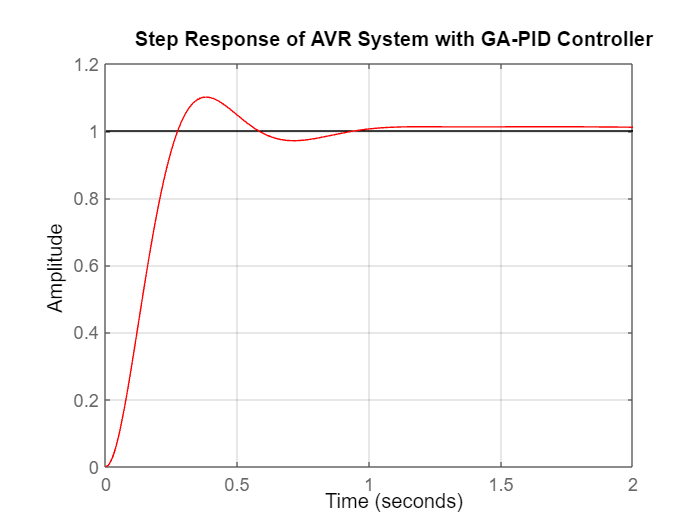


pid_controller = pid(kp_optimized, ki_optimized, kd_optimized);
sys_with_pid = feedback(pid_controller * AVR_ForwardPath, AVR_BackwardPath);

t = 0:0.01:2;
step(sys_with_pid, t, 'r');
grid on;
title('Step Response of AVR System with GA-PID Controller');

## Performance Criterion : W(k)

function W = PerformanceCriterion(Kp, Ki, Kd, beta)
    num_f = 10;
    den_f = [0.04, 0.54, 1.5, 1];
    AVR_ForwardPath = tf(num_f, den_f);
    
    num_b = 1;
    den_b = [0.01, 1];
    AVR_BackwardPath = tf(num_b, den_b);

    pid_controller = pid(Kp, Ki, Kd);

    sys_with_pid = feedback(pid_controller * AVR_ForwardPath, AVR_BackwardPath);
    
    [y, t] = step(sys_with_pid);
    info = stepinfo(y, t);

    Ess = abs(1 - y(end));                  % Steady-state error
    Mp = (max(y)- y(end)) / y(end);         % Maximum overshoot
    Ts = info.SettlingTime;                 % Settling time
    Tr = info.RiseTime;                     % Rise time

    W = (1-exp(-beta))*(Mp + Ess) + (exp(-beta))*(Ts - Tr);
end